addpath(genpath('../helperFunctions'))

stimPath = '../stimulusSets/isettreeshrew/treeshrew_10/';
taskType = 'Camel_novel_v2_test_nn';
stimSet = [taskType,'_quad/original/merged/'];

d = natsortfiles(dir('../4_treeShrewBehavior/behaviorData/shrewData.mat'));
load([d(end).folder,'/',d(end).name])

targ_idx = unique(allData.(taskType).T_Expt_ID);
train_targ_val = [0 6 9 13 17 32 38 40 44 55 60 65];
test_targ_val = setdiff(targ_idx,train_targ_val);
[~,train_targ_idx] = ismember(train_targ_val,targ_idx);
train_targ_idx(train_targ_idx==0) = [];
[~,test_targ_idx] = ismember(test_targ_val,targ_idx);

dist_idx = unique(allData.(taskType).D_Expt_ID);
if strcmp(taskType,'Camel_Rhino_test_nn')
    distractor = 'rhino';
    train_dist_val = [0 3 11 16 70 76 92];
else
    distractor = 'wrench';
    train_dist_val = [0 14 26 83 87 92 93];
end
test_dist_val = setdiff(dist_idx,train_dist_val);
[~,train_dist_idx] = ismember(train_dist_val,dist_idx);
train_dist_idx(train_dist_idx==0) = [];
[~,test_dist_idx] = ismember(test_dist_val,dist_idx);

allImgs = natsortfiles(dir([stimPath,stimSet]));
allImgs = allImgs(3:end);

for tt = 1:length(targ_idx)
    img = double(imread(sprintf('%s%s/camel_%d.png',stimPath,stimSet,targ_idx(tt))));
    img_targ(tt,:) = img(:);
end

for dd = 1:length(dist_idx)
    img = double(imread(sprintf('%s%s/%s_%d.png',stimPath,stimSet,distractor,dist_idx(dd))));
    img_dist(dd,:) = img(:);
end

train_raw = [img_targ(train_targ_idx,:);img_dist(train_dist_idx,:)];
test_raw = [img_targ(test_targ_idx,:);img_dist(test_dist_idx,:)];

mu = mean(train_raw);
sd = std(train_raw);
sd(sd == 0) = 1;

trainX = (train_raw - mu) ./ sd;
testX  = (test_raw  - mu) ./ sd;

trainY = [zeros(length(train_targ_idx),1); ones(length(train_dist_idx),1)];
testY = [zeros(length(test_targ_idx),1); ones(length(test_dist_idx),1)];

Mdl = fitcsvm(trainX, trainY);
pred_train = predict(Mdl,trainX);
pred = predict(Mdl, testX);
perf = sum((testY-pred)==0)/length(pred);

perf_samp = nan(1,1000);
for i = 1:1000
    y_shuf = trainY(randperm(length(trainY)));
    Mdl_shuf = fitcsvm(trainX, y_shuf);
    pred_shuf = predict(Mdl_shuf, testX);
    perf_samp(i) = sum((testY - pred_shuf) == 0) / length(testY);
end
p_val = mean(perf_samp >= perf);

figure;
histogram(perf_samp)
hold on;
xline(perf)
targ_norm = (img_targ - mu) ./ sd;
dist_norm  = (img_dist  - mu) ./ sd;

pred = nan(1,height(allData.(taskType)));
relative_score = nan(1,height(allData.(taskType)));
for tr = 1:height(allData.(taskType))
    if allData.(taskType).ctch(tr)==1
        continue
    end
    targ = allData.(taskType).T_Expt_ID(tr);
    tidx = find(targ_idx==targ);
    dist = allData.(taskType).D_Expt_ID(tr);
    didx = find(dist_idx==dist);
    [~,targ_score] = predict(Mdl, targ_norm(tidx,:));
    [~,dist_score] = predict(Mdl, dist_norm(didx,:));
    relative_score(tr) = targ_score(:,1) - dist_score(:,1);
    pred(tr) = relative_score(tr) > 0;
end
disp(mean(pred,'omitnan'))
disp(length(pred(~isnan(pred))))

figure();
histogram(relative_score(~isnan(relative_score)))
xline(0)

## camel rhino

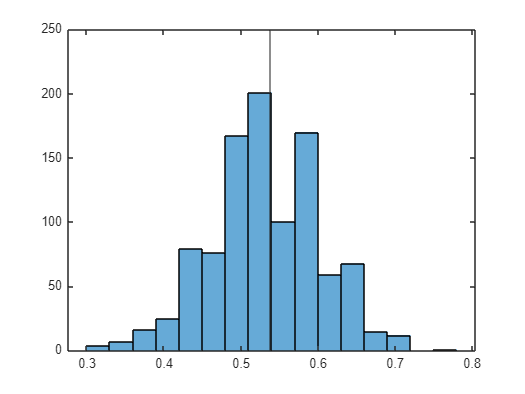

addpath(genpath('../helperFunctions'))

stimPath = '../stimulusSets/isettreeshrew/treeshrew_10/';
taskType = 'Camel_Rhino_test_nn';
stimSet = [taskType,'_quad/original/merged/'];

d = natsortfiles(dir('../4_treeShrewBehavior/behaviorData/shrewData.mat'));
load([d(end).folder,'/',d(end).name])

targ_idx = unique(allData.(taskType).T_Expt_ID);
train_targ_val = [0 6 9 13 17 32 38 40 44 55 60 65];
test_targ_val = setdiff(targ_idx,train_targ_val);
[~,train_targ_idx] = ismember(train_targ_val,targ_idx);
train_targ_idx(train_targ_idx==0) = [];
[~,test_targ_idx] = ismember(test_targ_val,targ_idx);

dist_idx = unique(allData.(taskType).D_Expt_ID);
if strcmp(taskType,'Camel_Rhino_test_nn')
    distractor = 'rhino';
    train_dist_val = [0 3 11 16 70 76 92];
else
    distractor = 'wrench';
    train_dist_val = [0 14 26 83 87 92 93];
end
test_dist_val = setdiff(dist_idx,train_dist_val);
[~,train_dist_idx] = ismember(train_dist_val,dist_idx);
train_dist_idx(train_dist_idx==0) = [];
[~,test_dist_idx] = ismember(test_dist_val,dist_idx);

allImgs = natsortfiles(dir([stimPath,stimSet]));
allImgs = allImgs(3:end);

for tt = 1:length(targ_idx)
    img = double(imread(sprintf('%s%s/camel_%d.png',stimPath,stimSet,targ_idx(tt))));
    img_targ(tt,:) = img(:);
end

for dd = 1:length(dist_idx)
    img = double(imread(sprintf('%s%s/%s_%d.png',stimPath,stimSet,distractor,dist_idx(dd))));
    img_dist(dd,:) = img(:);
end

train_raw = [img_targ(train_targ_idx,:);img_dist(train_dist_idx,:)];
test_raw = [img_targ(test_targ_idx,:);img_dist(test_dist_idx,:)];

mu = mean(train_raw);
sd = std(train_raw);
sd(sd == 0) = 1;

trainX = (train_raw - mu) ./ sd;
testX  = (test_raw  - mu) ./ sd;

trainY = [zeros(length(train_targ_idx),1); ones(length(train_dist_idx),1)];
testY = [zeros(length(test_targ_idx),1); ones(length(test_dist_idx),1)];

Mdl = fitcsvm(trainX, trainY);
pred_train = predict(Mdl,trainX);
pred = predict(Mdl, testX);
perf = sum((testY-pred)==0)/length(pred);

perf_samp = nan(1,1000);
for i = 1:1000
    y_shuf = trainY(randperm(length(trainY)));
    Mdl_shuf = fitcsvm(trainX, y_shuf);
    pred_shuf = predict(Mdl_shuf, testX);
    perf_samp(i) = sum((testY - pred_shuf) == 0) / length(testY);
end
p_val = mean(perf_samp >= perf);

figure;
histogram(perf_samp)
hold on;
xline(perf)

targ_norm = (img_targ - mu) ./ sd;
dist_norm  = (img_dist  - mu) ./ sd;

pred = nan(1,height(allData.(taskType)));
relative_score = nan(1,height(allData.(taskType)));
for tr = 1:height(allData.(taskType))
    if allData.(taskType).ctch(tr)==1
        continue
    end
    targ = allData.(taskType).T_Expt_ID(tr);
    tidx = find(targ_idx==targ);
    dist = allData.(taskType).D_Expt_ID(tr);
    didx = find(dist_idx==dist);
    [~,targ_score] = predict(Mdl, targ_norm(tidx,:));
    [~,dist_score] = predict(Mdl, dist_norm(didx,:));
    relative_score(tr) = targ_score(:,1) - dist_score(:,1);
    pred(tr) = relative_score(tr) > 0;
end
disp(mean(pred,'omitnan'))

    0.9702



disp(length(pred(~isnan(pred))))

       22915



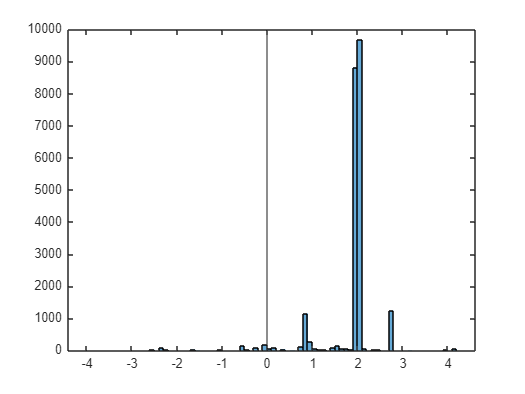


figure();
histogram(relative_score(~isnan(relative_score)))
xline(0)

## Average across trials for each target-distractor pair

T = allData.(taskType);

% Get unique target-distractor pairs
pairs = unique([T.T_Expt_ID, T.D_Expt_ID], 'rows');

nPairs = size(pairs,1);

pair_score = nan(nPairs,1);
pair_performance = nan(nPairs,1);
n_trials = nan(nPairs,1);

for p = 1:nPairs

    targ = pairs(p,1);
    dist = pairs(p,2);

    % Trials belonging to this pair
    idx = T.T_Expt_ID == targ & T.D_Expt_ID == dist;

    % Average model score difference
    pair_score(p) = mean(relative_score(idx), 'omitnan');

    % Average behavioral performance
    pair_performance(p) = mean(T.correct(idx), 'omitnan');

    % Number of trials
    % n_trials(p) = sum(idx & ~isnan(relative_score));
end


%% Correlation

valid = ~isnan(pair_score) & ~isnan(pair_performance);

[r, pval] = corr(pair_score(valid), pair_performance(valid), ...
                 'Type', 'Pearson');

fprintf('Pearson r = %.3f, p = %.4f\n', r, pval);

Pearson r = 0.250, p = 0.0000


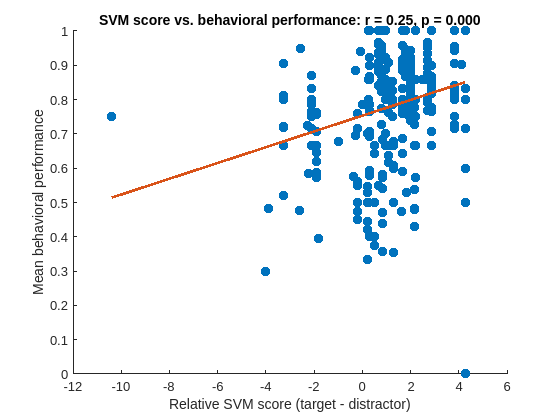



%% Plot

figure;
scatter(pair_score(valid), pair_performance(valid), 50, 'filled');

xlabel('Relative SVM score (target - distractor)');
ylabel('Mean behavioral performance');
title(sprintf('SVM score vs. behavioral performance: r = %.2f, p = %.3f', ...
    r, pval));

hold on;

% Regression line
x = pair_score(valid);
y = pair_performance(valid);

b = polyfit(x, y, 1);
xfit = linspace(min(x), max(x), 100);
yfit = polyval(b, xfit);

plot(xfit, yfit, 'LineWidth', 2);